# Equacions diferencials - Pràctica 33

## **Exercici  **$y^{\prime}(t)=1+t-y(t)\,,\quad y(0)=1,\quad 0\leq t\leq 1\,.$

Solució analítica

format longE
syms y(t)
eqn = diff(y,t) == 1+t-y;
cond = y(0) == 1;
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = t+{\mathrm{e}}^{-t}$$

La solució es pot respresentar a l'interval [0,3]

%fplot(ySol,[0,1])

## Solucions aproximades numèricament

# `Mètode d'Euler`

- `Mètode d'Euler prenent h=0.1, h = 0.05`

a = 0; alpha = 1;    % y(a) = alpha
b = 1;               % y(b) = ...
f = @(t,y)(1+t-y);
h = 0.1;
[ Y1 ] = Euler( f,a,b,h,alpha )

Y1 =      1.000000000000000e+00     1.000000000000000e+00     1.010000000000000e+00     1.029000000000000e+00     1.056100000000000e+00     1.090490000000000e+00     1.131441000000000e+00     1.178296900000000e+00     1.230467210000000e+00     1.287420489000000e+00     1.348678440100000e+00


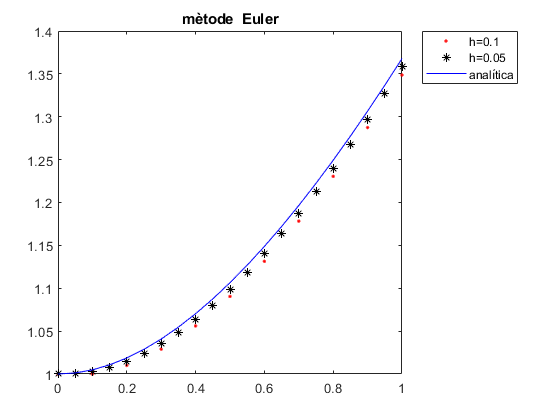

% disp([a:h:b;w]')
x = a:h:b; 
h = 0.05;
[ Y2 ] = Euler( f,a,b,h,alpha );
x2 = a:h:b; 
plot(x,Y1,'r.',x2,Y2,'*k',x2,ySol(x2),'b')
legend('h=0.1','h=0.05','analítica','location','bestoutside')
title('mètode  Euler')

errorlocal = abs(Y2-double(ySol(x2)))

errorlocal =                          0     1.229424500714060e-03     2.337418035959660e-03     3.332976425057810e-03     4.224503077981945e-03     5.019845571404780e-03     5.726330056717854e-03     6.350793624963380e-03     6.899614746576743e-03     7.378741897164032e-03     7.793720474254640e-03     8.149718104026871e-03     8.451548431389622e-03     8.703693481511010e-03     8.910324675879933e-03     9.075322581261647e-03     9.202295465456034e-03     9.294596729549465e-03     9.355341282380802e-03     9.387420919193756e-03     9.393518762900177e-03


errorGlobal = abs(Y2(end)-double(ySol(1)))

errorGlobal =      9.393518762900177e-03


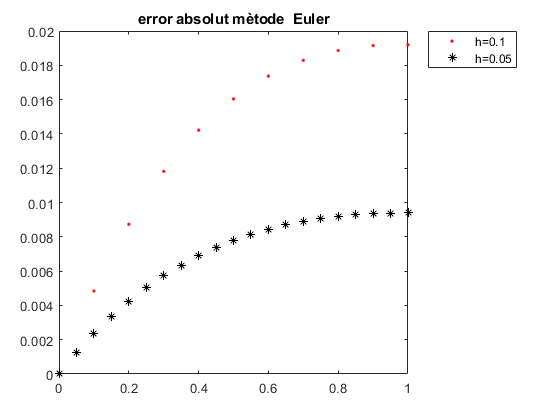

plot(x,abs(Y1-double(ySol(x))),'r.',x2,abs(Y2-double(ySol(x2))),'*k')
legend('h=0.1','h=0.05','location','bestoutside')
title('error absolut mètode  Euler')

# `Mètode d'Euler modificat`

- `Mètode d'Euler modificat`

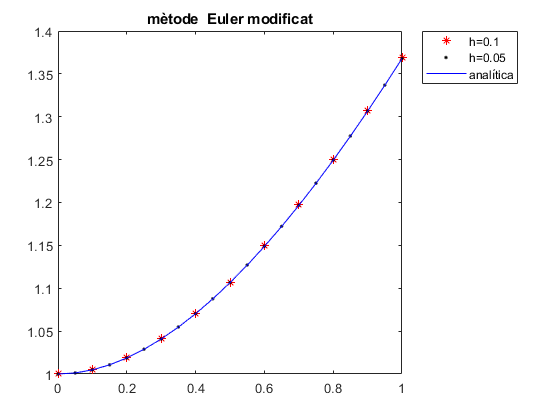

a = 0; alpha = 1;    % y(a) = alpha
b = 1;               % y(b) = ...
f = @(t,y)(1+t-y);
h = 0.1;
[ YM1 ] = EulerMOD( f,a,b,h,alpha );
% disp([a:h:b;w]')
x = a:h:b; 
h = 0.05;
[ YM2 ] = EulerMOD( f,a,b,h,alpha );
x2 = a:h:b; 
plot(x,YM1,'r*',x2,YM2,'.k',x2,ySol(x2),'b')
legend('h=0.1','h=0.05','analítica','location','bestoutside')
title('mètode  Euler modificat')

errorlocal = YM2-double(ySol(x2))

errorlocal =                          0     2.057549928591307e-05     3.914446404040817e-05     5.585365306726153e-05     7.084028383452790e-05     8.423261402312754e-05     9.615048904554335e-05     1.067058574752977e-04     1.160032562101954e-04     1.241402670983938e-04     1.312079466557758e-04     1.372912304120621e-04     1.424693133411647e-04     1.468160077424674e-04     1.504000798717708e-04     1.532855665415944e-04     1.555320728414689e-04     1.571950520709020e-04     1.583260689095312e-04     1.589730467939088e-04     1.591805004146352e-04


errorGlobal = YM2(end)-double(ySol(1))

errorGlobal =      1.591805004146352e-04


- `Mètode de Heun`

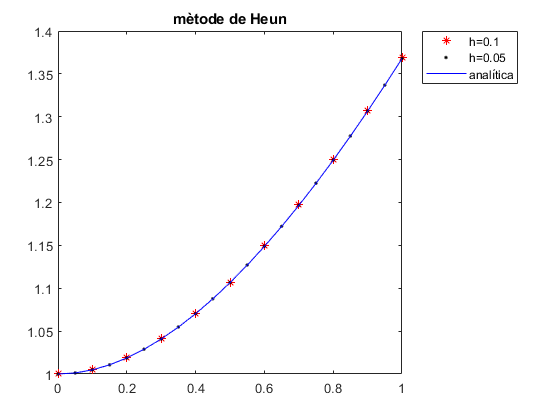

a = 0; alpha = 1;    % y(a) = alpha
b = 1;               % y(b) = ...
f = @(t,y)(1+t-y);
h = 0.1;
[ YH1 ] = Heun( f,a,b,h,alpha );
x = a:h:b; 
h = 0.05;
[ YH2 ] = Heun( f,a,b,h,alpha );
x2 = a:h:b; 
plot(x,YH1,'r*',x2,YH2,'.k',x2,ySol(x2),'b')
legend('h=0.1','h=0.05','analítica','location','bestoutside')
title('mètode de Heun')

errorlocal = YH2-double(ySol(x2))

errorlocal =                          0     2.057549928591307e-05     3.914446404040817e-05     5.585365306726153e-05     7.084028383452790e-05     8.423261402312754e-05     9.615048904554335e-05     1.067058574752977e-04     1.160032562101954e-04     1.241402670983938e-04     1.312079466557758e-04     1.372912304120621e-04     1.424693133411647e-04     1.468160077424674e-04     1.504000798717708e-04     1.532855665415944e-04     1.555320728414689e-04     1.571950520709020e-04     1.583260689095312e-04     1.589730467939088e-04     1.591805004146352e-04


errorGlobal = YH2(end)-double(ySol(1))

errorGlobal =      1.591805004146352e-04


# `Mètode RK4`

- `Mètode RK4`

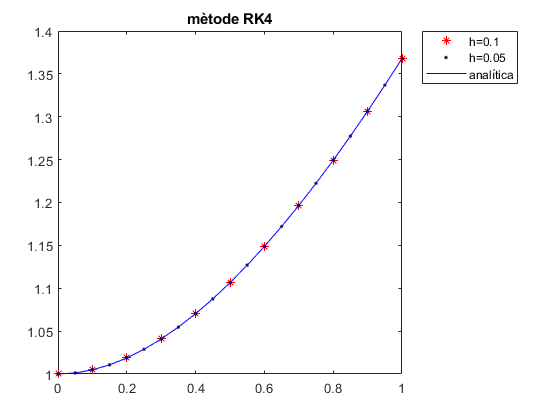

a = 0; alpha = 1;    % y(a) = alpha
b = 1;               % y(b) = ...
f = @(t,y)(1+t-y);
h = 0.1;
[ YK1 ] = RK4( f,a,b,h,alpha );
x = a:h:b; 
h = 0.05;
[ YK2 ] = RK4( f,a,b,h,alpha );
x2 = a:h:b; 
plot(x,YK1,'r*',x2,YK2,'.k',x2,ySol(x2),'b')
legend('h=0.1','h=0.05','analítica','location','bestoutside')
title('mètode RK4')

errorlocal = YK2-double(ySol(x2))

errorlocal =                          0     2.582619229585248e-09     4.913326856481603e-09     7.010551916764030e-09     8.891524183596289e-09     1.057234944035201e-08     1.206807587195158e-08     1.339276023415437e-08     1.455952869378052e-08     1.558063345008520e-08     1.646750802386521e-08     1.723081610727206e-08     1.788050107975891e-08     1.842583041700152e-08     1.887543743528397e-08     1.923736236975060e-08     1.951908834563199e-08     1.972757690538174e-08     1.986930175945645e-08     1.995027920642656e-08     1.997609744286422e-08


errorGlobal = YK2(end)-double(ySol(1))

errorGlobal =      1.997609744286422e-08


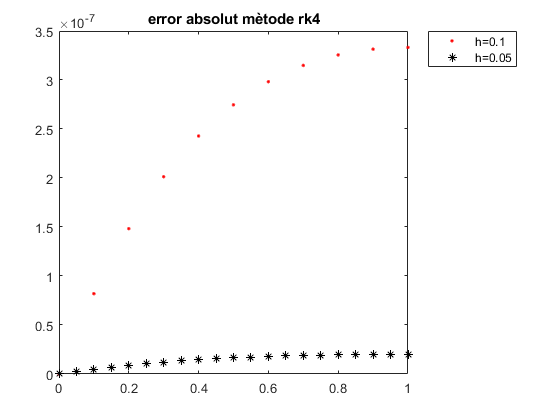

plot(x,abs(YK1-double(ySol(x))),'r.',x2,abs(YK2-double(ySol(x2))),'*k')
legend('h=0.1','h=0.05','location','bestoutside')
title('error absolut mètode rk4')

# `ode45`

- `Fent ús de la instrucció ode45`

tspan = [0 1];
y0 = 1;        
ode = @(t,y) (1+t-y);
[t1,y1] = ode23(ode, tspan, y0);
disp([t1,y1])

                         0     1.000000000000000e+00
     1.000000000000000e-01     1.004833333333333e+00
     2.000000000000000e-01     1.018723361111111e+00
     3.000000000000000e-01     1.040808187912037e+00
     4.000000000000000e-01     1.070307942029075e+00
     5.000000000000000e-01     1.106516969545975e+00
     6.000000000000000e-01     1.148796771277516e+00
     7.000000000000000e-01     1.196569611877606e+00
     7.999999999999999e-01     1.249312737147253e+00
     8.999999999999999e-01     1.306553141662073e+00
     1.000000000000000e+00     1.367862834347233e+00



[t2,y2] = ode45(ode, tspan, y0);
disp([t2,y2])

                         0     1.000000000000000e+00
     2.500000000000000e-02     1.000309908082357e+00
     5.000000000000000e-02     1.001229418796875e+00
     7.500000000000001e-02     1.002743483983398e+00
     1.000000000000000e-01     1.004837418333333e+00
     1.250000000000000e-01     1.007496899304160e+00
     1.500000000000000e-01     1.010707971546881e+00
     1.750000000000000e-01     1.014457018923110e+00
     2.000000000000000e-01     1.018730753616132e+00
     2.250000000000000e-01     1.023516216053548e+00
     2.500000000000000e-01     1.028800778913400e+00
     2.750000000000000e-01     1.034572121804183e+00
     3.000000000000000e-01     1.040818221412125e+00
     3.250000000000001e-01     1.047527351431194e+00
     3.500000000000000e-01     1.054688086187990e+00
     3.750000000000000e-01     1.062289277731269e+00
     4.000000000000000e-01     1.070320046916839e+00
     4.250000000000000e-01     1.078769783344223e+00
     4.500000000000000e-01     1.0876281486365

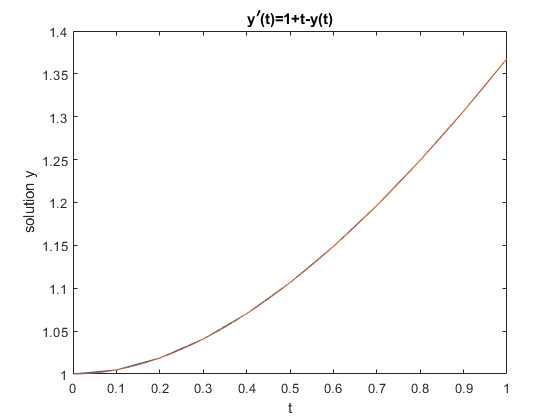

% Plot solution
plot(t1,y1,t2,y2)
xlabel('t')
ylabel('solution y')
title('y^{\prime}(t)=1+t-y(t)')

Isoclines del camp de direccions y'=f(t,y)

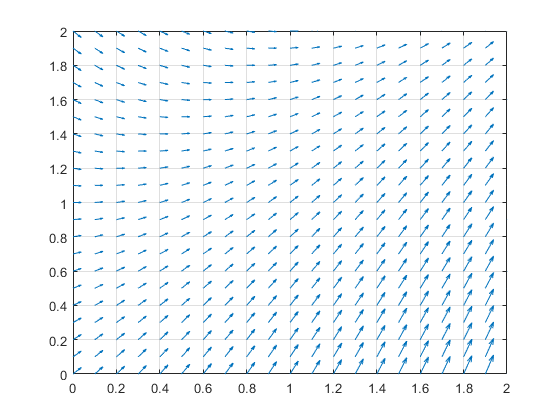

t=0:.1:2; 
y=0:0.1:2;
[TT,YY] = meshgrid(t,y);
DT = ones(size(TT));
f=@(t,y) (1+t-y);
DY = f(TT,YY);
% Gràfic
figure(1)
quiver(TT,YY,DT,DY);grid,axis([0,2,0,2])